# Lab 3

clear; close; clc;

%bring in functions from ae 445
% addpath(genpath('AE 445')); % unsure why this line is broken
%addpath('C:\Users\satur\OneDrive - University of Kansas\MATLAB\AE 445');

## initialize constants

%all units si
% rho in  kg/m^3
rho_air = 1.225; 
rho_mano = 826;

mu_air = 1.78e-5; % kg/(m*s)
nu_air = mu_air/rho_air; % 1/(m*s*kg^2)

pitoLEDist = .3; % m 
VertPitoSep = 0.188333e-2; % m vertical seperation of pito tubes (.188333cm)

g= 9.81; %  m/s^2

## Read in Data

if(~isfile("Lab_3_Data"))
    Data = readmatrix("Lab3_data(1).xlsx");
    Data = Data(:,2:end);
    hs = Data(1,:);
    ht = Data(2,:);
    h = Data(3:end,:);
    save("Lab_3_Data","hs","ht","h");
else
    load("Lab_3_Data");
end

## convert head to presssure

% pt = head2press(rho_mano, ht*.01)
% ps = head2press(rho_mano, hs*.01)
% 
% p = arrayfun(@(h) head2press(rho_mano, h), h*.01);

## Calculate velocities

v = press2velo(h,hs,rho_mano,rho_air); % for boundry layer pitos
vf = sqrt(2*rho_mano*g*abs(ht-hs)*.01/rho_air); % for free stream

% if velocity is not freestream by the 10th pito tube, set it equal to the
% velocity of the 10th pito. something changed between measurment points
for col = 1:length(vf)
    if vf(col) > max(v(:,col)) * .99 % this is edge of boundry layer
        vf(col) = max(v(:,col));
    end
end
vf;

## Calulate Reynold numbers

Re = rho_air * vf * pitoLEDist / mu_air;

## Calculate boundry layer thickness from theory

delta_l = laminarBoundryLayerThickness(pitoLEDist,Re);
delta_t = tubulentBoundryLayerThickness(pitoLEDist,Re);

%calculate latminar tubulent transistion distances
xl = getLaminarTurbulentBoundryLayerDistance(3e5,vf,nu_air); %calculate distance at which transistion begins
xf = getLaminarTurbulentBoundryLayerDistance(1e6,vf,nu_air); %calculate distance at which transistion ends

## Calulate boundry layer thickness from experimantal values

vRat = zeros(size(v));
vRat2 = zeros(size(v));
delta_e = zeros(1,length(vf));
delta_e(:) = 10*VertPitoSep;
boundryPito = zeros(1,length(vf));
for i = 1:length(vf)
    vRat(:,i) = v(:,i)/vf(i);
    vRat2(:,i) = v(:,i)/vf(i);
    for j = 1:size(vRat,1)
        %vRat(j,i)
        if(vRat(j,i) >= .99)
            delta_e(i) = VertPitoSep*j;
            boundryPito(i) = j;
            break;
        end
    end
end
vRat;
delta_e;


## visulalize the boundry layers

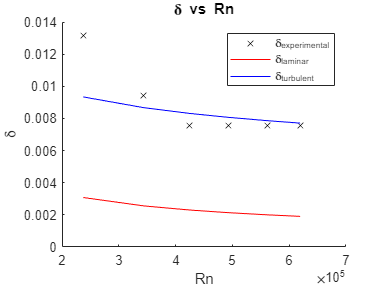

figure;
ePlot = scatter(Re,delta_e,'xk'); hold on; set(ePlot,'DisplayName','\delta_{experimental}');
lPlot = plot(Re,delta_l,'r'); hold on; set(lPlot,'DisplayName','\delta_{laminar}');
tPlot = plot(Re,delta_t,'b'); set(tPlot,'DisplayName','\delta_{turbulent}'); hold off;
legend; title("\delta vs Rn"); ylabel("\delta"); xlabel("Rn");

## Plot velocity profile of a boundry layer

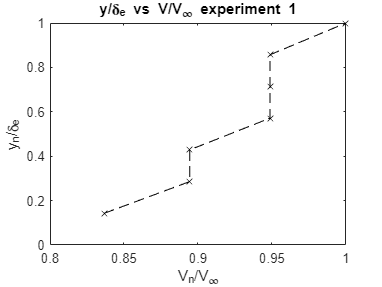

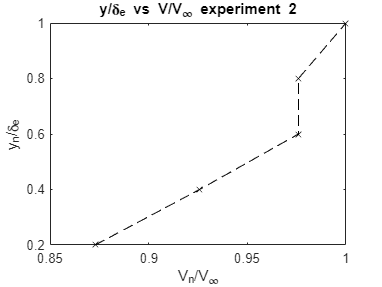

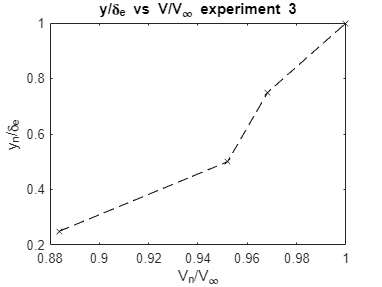

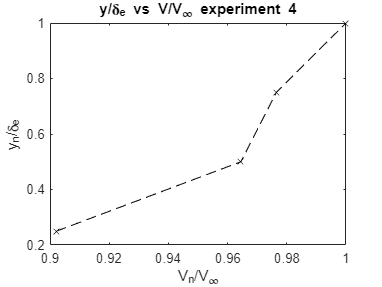

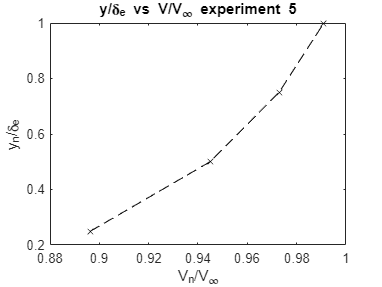

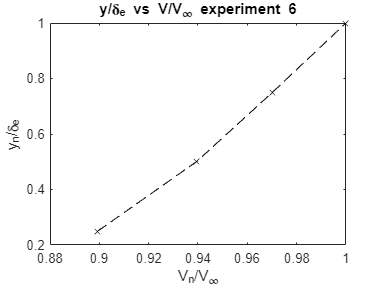

%choose a nice one

for experiment = 1:6
    figure; 
    vProfile = v(1:boundryPito(experiment),experiment)/vf(experiment); %normalized velocity profile
    heights = [.188333e-2:.188333e-2:delta_e(experiment)];
    heights = heights/max(heights); %normalize
    plot(vProfile,heights,'--xk'); hold on; title( "y/\delta_e vs V/V_\infty" + sprintf(" experiment %d",experiment)); xlabel("V_n/V_\infty"); ylabel("y_n/\delta_e")
end

## Compare boundry layer thicknesses

erorrs = zeros(2,length(delta_e));
turbErrPer = abs(delta_e-delta_t)*100./delta_e; % percent error turbulent
lamErrPer = abs(delta_e-delta_l)*100./delta_e; % percent error turbulent

## Make tables for LaTeX report

%velocities
expLab = "";
for i=1:6
    expLab = horzcat(expLab,sprintf("Experiment %d",i));
end
expLab = expLab(2:end);%remove the empty entry


rowLab = "";
for i=1:10
    rowLab = horzcat(rowLab,sprintf("Pitot %d",i));
end
rowLab = rowLab(2:end);%remove the empty entry

vTab = array2table(v,"VariableNames",expLab,"RowNames",rowLab,"DimensionNames",["Experiment","Pitot"]);
table2latex(vTab);

Output path is not defined. The table will be written in table.tex.



%velocity ratios

rowLab = "";
for i=1:10
    rowLab = horzcat(rowLab,sprintf("$V_%d/V_\\infty$",i));
end
rowLab = rowLab(2:end);%remove the empty entry

vTab = array2table(vRat,"VariableNames",expLab,"RowNames",rowLab,"DimensionNames",["Experiment","Pitot"]);
table2latex(vTab);

Output path is not defined. The table will be written in table.tex.



% medly table

rowLab = ["$V_\\infty$","$Rn$","$\\delta_laminar$","$\\delta_turbulent$","$\\delta_experimental$"];

vTab = array2table([vf; Re; delta_l; delta_t; delta_e],"VariableNames",expLab,"RowNames",rowLab,"DimensionNames",["Experiment","Pitot"]);
table2latex(vTab);

Output path is not defined. The table will be written in table.tex.



% percent error
rowLab = ["$error_{\delta_{laminar}} \%$","$error_{\delta_{turbulent}} \%$"];
vTab = array2table([lamErrPer;turbErrPer],"VariableNames",expLab,"RowNames",rowLab,"DimensionNames",["Experiment","Pitot"]);
table2latex(vTab);

Output path is not defined. The table will be written in table.tex.



rowLab = ["$x_{measure}-x_{transition}$","$x_{measure}-x_{turbulent}$"];
vTab = array2table([pitoLEDist-xl;pitoLEDist-xf],"VariableNames",expLab,"RowNames",rowLab,"DimensionNames",["Experiment","Pitot"]);
table2latex(vTab);

Output path is not defined. The table will be written in table.tex.


## Save figures

Dot indexing into the result of a function call requires parentheses after the function name. The supported syntax is 'gca().Title'.

Error in saveAllFig (line 15)
            FigName = gca.Title; 

saveAllFig("Lab_3_figures");

function p = head2press(rho_mano,h)
    g = 9.81;
    p = rho_mano*g*h;
end

function v = press2velo(ht,hs,rho_mano,rho_air)
    g = 9.81;
    v = sqrt(2*rho_mano*g*abs(ht-hs)*.01/rho_air); %the .01 is cm to m
end

